%% AE 6355 - Individual Project - Parameter Sensitivity Study
% One-at-a-time (OAT) sweep of entry flight path angle, ballistic
% coefficient, L/D, bank angle, and entry velocity, holding all other
% parameters at a nominal baseline. 
%
% Companion to EDL_BaseProject.mlx - shares the same EOM, atmosphere,
% gravity model, and sign conventions, reimplemented standalone since
% this sweep does not need the EquiFlow aero machinery.

clear; clc; close all;

%% -----------------------------------------------------------------
%% BASELINE (NOMINAL) CASE AND OAT RANGES
%% -----------------------------------------------------------------
% Baseline uses a nonzero lifting condition (not the ballistic Stardust
% case) so both the L/D and bank-angle sweeps produce meaningful
% trajectory changes; a ballistic (L/D=0) baseline would make sigma
% have no physical effect at all.
baseline.gamma_e_deg = 8.21;       % deg, positive below local horizontal
baseline.beta        = 61;          % kg/m^2
baseline.LD          = 0.30;
baseline.sigma_deg   = 45;          % deg
baseline.Ve          = 12799;       % m/s

% OAT min/max ranges (assumptions, documented in the report). L/D and
% bank-angle ranges are centered on the baseline so both perturbation
% directions are informative.
ranges.gamma_e_deg = [1, 15];       % deg; 1 deg intended to demonstrate skip-out
ranges.beta         = [20, 200];    % kg/m^2
ranges.LD           = [0, 0.60];    % centered on baseline (0.30)
ranges.sigma_deg    = [0, 90];      % deg; centered on baseline (45)
ranges.Ve           = [7500, 13000];% m/s

% Build the 11-case OAT matrix: 1 baseline + (5 parameters x 2 endpoints).
case_names = {};
case_params = {};

case_names{end+1} = 'baseline';
case_params{end+1} = baseline;

param_fields = {'gamma_e_deg','beta','LD','sigma_deg','Ve'};
for k = 1:numel(param_fields)
    fname = param_fields{k};
    for endpoint = 1:2
        c = baseline;
        c.(fname) = ranges.(fname)(endpoint);
        label = sprintf('%s_%s', fname, ternary(endpoint==1,'low','high'));
        case_names{end+1} = label; %#ok<SAGROW>
        case_params{end+1} = c;    %#ok<SAGROW>
    end
end

%% -----------------------------------------------------------------
%% RUN ALL CASES
%% -----------------------------------------------------------------
n_cases = numel(case_names);
results = struct([]);

for i = 1:n_cases
    c = case_params{i};
    r = run_entry_trajectory(c.Ve, c.gamma_e_deg, c.beta, c.LD, c.sigma_deg);
    r.case_name = case_names{i};
    r.gamma_e_deg = c.gamma_e_deg;
    r.beta = c.beta;
    r.LD = c.LD;
    r.sigma_deg = c.sigma_deg;
    r.Ve = c.Ve;
    results = [results, r]; %#ok<AGROW>
    fprintf('[%2d/%2d] %-16s -> %s (peak load %.1f g, peak qdot %.1f W/cm^2, h_min=%.1f km)\n', ...
        i, n_cases, case_names{i}, r.outcome, r.peak_load, r.peak_qdot, r.h_min/1000);
end

[ 1/11] baseline         -> ground impact (peak load 26.9 g, peak qdot 746.8 W/cm^2, h_min=-0.0 km)
[ 2/11] gamma_e_deg_low  -> atmospheric skip-out (peak load 0.0 g, peak qdot 23.1 W/cm^2, h_min=118.4 km)
[ 3/11] gamma_e_deg_high -> ground impact (peak load 85.2 g, peak qdot 1193.2 W/cm^2, h_min=-0.0 km)
[ 4/11] beta_low         -> ground impact (peak load 29.6 g, peak qdot 443.4 W/cm^2, h_min=-0.0 km)
[ 5/11] beta_high        -> ground impact (peak load 23.8 g, peak qdot 1293.5 W/cm^2, h_min=-0.0 km)
[ 6/11] LD_low           -> ground impact (peak load 41.6 g, peak qdot 810.6 W/cm^2, h_min=-0.0 km)
[ 7/11] LD_high          -> atmospheric skip-out (peak load 21.4 g, peak qdot 692.3 W/cm^2, h_min=62.9 km)
[ 8/11] sigma_deg_low    -> atmospheric skip-out (peak load 23.0 g, peak qdot 723.1 W/cm^2, h_min=60.7 km)
[ 9/11] sigma_deg_high   -> ground impact (peak load 43.4 g, peak qdot 810.6 W/cm^2, h_min=-0.0 km)
[10/11] Ve_low           -> ground impact (peak load 17.0 g, peak qdot 189.7 W


%% -----------------------------------------------------------------
%% SUMMARY TABLE
%% -----------------------------------------------------------------
fprintf('\n=== OAT SENSITIVITY STUDY SUMMARY ===\n');


=== OAT SENSITIVITY STUDY SUMMARY ===


fprintf('%-16s %8s %8s %6s %8s %9s | %-20s %9s %10s %9s %9s\n', ...
    'case', 'gamma_e', 'beta', 'LD', 'sigma', 'Ve', 'outcome', 'peak_g', 'peak_qdot', 'Q_total', 'h_min_km');

case              gamma_e     beta     LD    sigma        Ve | outcome                 peak_g  peak_qdot   Q_total  h_min_km


for i = 1:n_cases
    r = results(i);
    fprintf('%-16s %8.2f %8.1f %6.2f %8.1f %9.0f | %-20s %9.2f %10.2f %9.1f %9.2f\n', ...
        r.case_name, r.gamma_e_deg, r.beta, r.LD, r.sigma_deg, r.Ve, ...
        r.outcome, r.peak_load, r.peak_qdot, r.Q_total, r.h_min/1000);
end

baseline             8.21     61.0   0.30     45.0     12799 | ground impact            26.88     746.82   30424.1     -0.00
gamma_e_deg_low      1.00     61.0   0.30     45.0     12799 | atmospheric skip-out      0.01      23.10     639.9    118.42
gamma_e_deg_high    15.00     61.0   0.30     45.0     12799 | ground impact            85.19    1193.21   15802.6     -0.00
beta_low             8.21     20.0   0.30     45.0     12799 | ground impact            29.62     443.36   16319.5     -0.00
beta_high            8.21    200.0   0.30     45.0     12799 | ground impact            23.83    1293.49   59501.0     -0.00
LD_low               8.21     61.0   0.00     45.0     12799 | ground impact            41.58     810.59   21869.9     -0.00
LD_high              8.21     61.0   0.60     45.0     12799 | atmospheric skip-out     21.38     692.33   24070.3     62.95
sigma_deg_low        8.21     61.0   0.30      0.0     12799 | atmospheric skip-out     23.02     723.11   25529.9     60.70



%% -----------------------------------------------------------------
%% CSV EXPORT
%% -----------------------------------------------------------------
case_name   = {results.case_name}';
gamma_e_deg = [results.gamma_e_deg]';
beta        = [results.beta]';
LD          = [results.LD]';
sigma_deg   = [results.sigma_deg]';
Ve          = [results.Ve]';
outcome     = {results.outcome}';
peak_load   = [results.peak_load]';
peak_load_t = [results.peak_load_t]';
peak_load_h = [results.peak_load_h]';
peak_load_V = [results.peak_load_V]';
peak_qdot   = [results.peak_qdot]';
peak_qdot_t = [results.peak_qdot_t]';
peak_qdot_h = [results.peak_qdot_h]';
peak_qdot_V = [results.peak_qdot_V]';
Q_total     = [results.Q_total]';
h_min       = [results.h_min]';
t_h_min     = [results.t_h_min]';
V_h_min     = [results.V_h_min]';
t_final     = [results.t_final]';
h_final     = [results.h_final]';
V_final     = [results.V_final]';

results_table = table(case_name, gamma_e_deg, beta, LD, sigma_deg, Ve, outcome, ...
    peak_load, peak_load_t, peak_load_h, peak_load_V, ...
    peak_qdot, peak_qdot_t, peak_qdot_h, peak_qdot_V, Q_total, ...
    h_min, t_h_min, V_h_min, t_final, h_final, V_final);
writetable(results_table, 'OAT_sweep_results.csv');
fprintf('\nResults written to OAT_sweep_results.csv\n');


Results written to OAT_sweep_results.csv


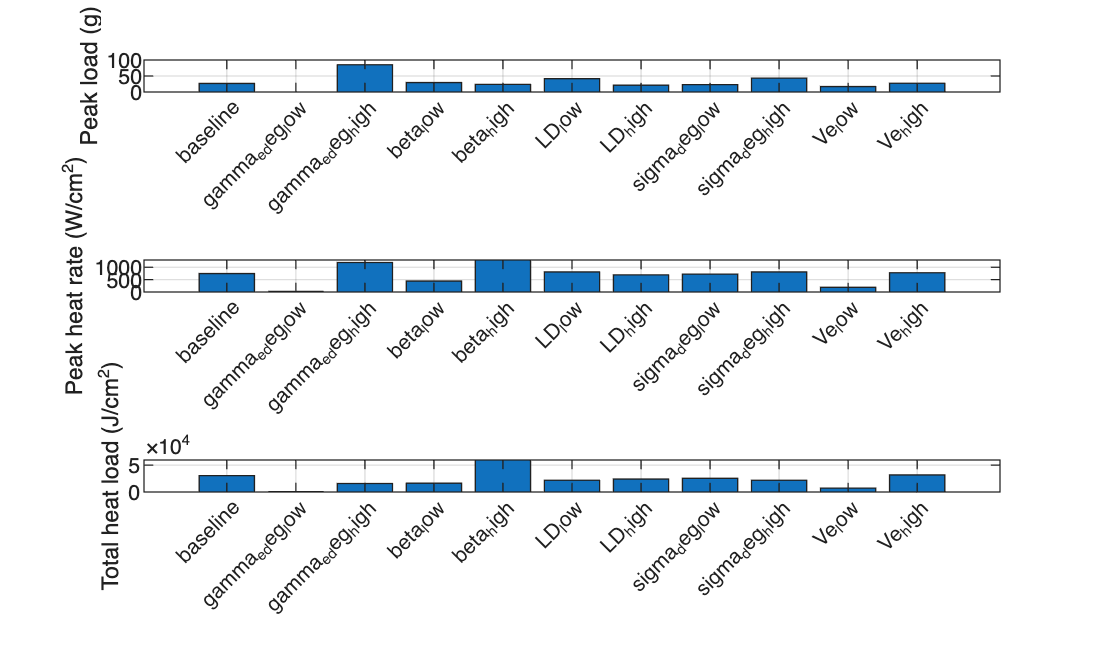


%% -----------------------------------------------------------------
%% PLOTS
%% -----------------------------------------------------------------
% Figure 1: bar charts of key outputs across all 11 cases.
figure;
subplot(3,1,1);
bar(peak_load); set(gca,'XTick',1:n_cases,'XTickLabel',case_name,'XTickLabelRotation',45);
ylabel('Peak load (g)'); grid on;

subplot(3,1,2);
bar(peak_qdot); set(gca,'XTick',1:n_cases,'XTickLabel',case_name,'XTickLabelRotation',45);
ylabel('Peak heat rate (W/cm^2)'); grid on;

subplot(3,1,3);
bar(Q_total); set(gca,'XTick',1:n_cases,'XTickLabel',case_name,'XTickLabelRotation',45);
ylabel('Total heat load (J/cm^2)'); grid on;

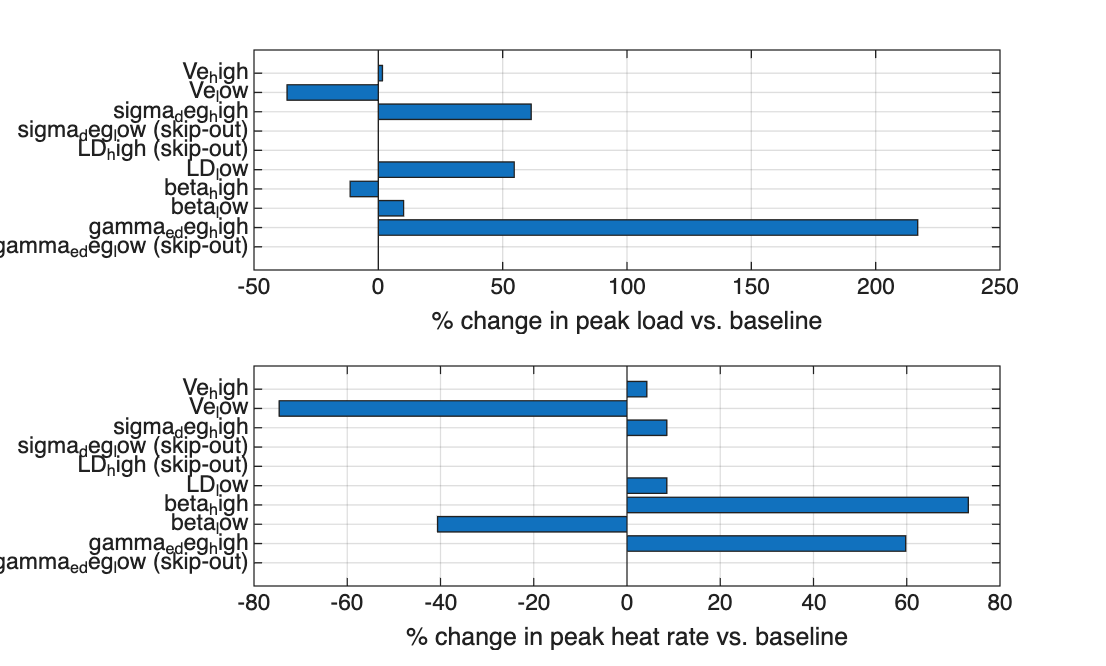


% Figure 2: tornado diagram, % change from baseline in peak load and
% peak heat rate for each swept parameter's low/high case. Skip-out
% cases are flagged in the label rather than assigned a % change.
baseline_load = results(1).peak_load;
baseline_qdot = results(1).peak_qdot;

tornado_labels = {};
tornado_load_pct = [];
tornado_qdot_pct = [];

for i = 2:n_cases
    if strcmp(results(i).outcome, 'atmospheric skip-out')
        tornado_labels{end+1} = [case_names{i} ' (skip-out)']; %#ok<SAGROW>
        tornado_load_pct(end+1) = NaN; %#ok<SAGROW>
        tornado_qdot_pct(end+1) = NaN; %#ok<SAGROW>
        continue;
    end
    tornado_labels{end+1} = case_names{i}; %#ok<SAGROW>
    tornado_load_pct(end+1) = 100*(results(i).peak_load - baseline_load)/baseline_load; %#ok<SAGROW>
    tornado_qdot_pct(end+1) = 100*(results(i).peak_qdot - baseline_qdot)/baseline_qdot; %#ok<SAGROW>
end

figure;
subplot(2,1,1);
barh(tornado_load_pct); set(gca,'YTick',1:numel(tornado_labels),'YTickLabel',tornado_labels);
xlabel('% change in peak load vs. baseline'); grid on;

subplot(2,1,2);
barh(tornado_qdot_pct); set(gca,'YTick',1:numel(tornado_labels),'YTickLabel',tornado_labels);
xlabel('% change in peak heat rate vs. baseline'); grid on;


%% -----------------------------------------------------------------
%% LOCAL FUNCTIONS
%% -----------------------------------------------------------------

function out = ternary(cond, a, b)
    if cond, out = a; else, out = b; end
end

function result = run_entry_trajectory(V0, gamma0_deg, beta_val, LD_val, sigma_deg)
% Runs one constant-beta/L-D entry trajectory and returns summary
% metrics. Shares the EOM, exponential atmosphere, inverse-square
% gravity, and Sutton-Graves heating conventions of EDL_BaseProject.m.

    Re  = 6378150;      % m
    g0  = 9.81;          % m/s^2
    rho0 = 1.225;        % kg/m^3
    H   = 7200;          % m
    h0  = 120000;        % m, entry interface altitude

    % Skip-out threshold sits above h0 so the upward-crossing event is
    % armed correctly; kept tight (h0+100) so genuine skip-out is
    % detected shortly after re-crossing the entry interface.
    skip_altitude = h0 + 100;   % m
    k_SG = 1.7415e-4;
    rn  = 0.2202;        % m, Stardust nose radius (reused for heating calc)

    gamma0 = gamma0_deg*pi/180;
    sigma0 = sigma_deg*pi/180;

    params.Re      = Re;
    params.beta    = @(V,h) beta_val;
    params.LD      = @(V,h) LD_val;
    params.sigma   = @(t) sigma0;
    params.g_fun   = @(h) g0*(Re/(Re+max(h,0)))^2;
    params.rho_fun = @(h) rho0*exp(-max(h,0)/H);

    x0 = [V0; gamma0; h0];
    tspan = [0 8000];   % extended ceiling for shallow/grazing entries
    opts = odeset('RelTol',1e-8, 'AbsTol',[1e-3 1e-10 1e-3], 'MaxStep',0.5, ...
        'Events', @(t,x) ground_skip_event(t,x,skip_altitude));
    [t, x, te, xe, ie] = ode45(@(t,x) EOM_3DOF(t, x, params), tspan, x0, opts);

    if isempty(ie)
        outcome = 'time limit';
        te = t(end);
        xe = x(end,:);
    elseif ie(end) == 1
        outcome = 'ground impact';
    else
        outcome = 'atmospheric skip-out';
    end

    V = x(:,1); h = x(:,3);

    rho_t = rho0*exp(-h/H);
    qdot_s = k_SG*sqrt(rho_t/rn).*V.^3 / 1e4;   % W/cm^2
    Q_total = trapz(t, qdot_s);                  % J/cm^2
    [qdot_peak, idx_heat] = max(qdot_s);

    drag_accel = rho_t.*V.^2./(2*beta_val);
    aero_accel = drag_accel*sqrt(1+LD_val^2);
    load_factor = aero_accel/g0;
    [load_peak, idx_load] = max(load_factor);
    [h_min, idx_min_h] = min(h);

    result.outcome     = outcome;
    result.t_final     = te;
    result.V_final     = xe(1);
    result.gamma_final = xe(2);
    result.h_final      = xe(3);
    result.peak_load    = load_peak;
    result.peak_load_t  = t(idx_load);
    result.peak_load_h  = h(idx_load);
    result.peak_load_V  = V(idx_load);
    result.peak_qdot    = qdot_peak;
    result.peak_qdot_t  = t(idx_heat);
    result.peak_qdot_h  = h(idx_heat);
    result.peak_qdot_V  = V(idx_heat);
    result.Q_total      = Q_total;
    result.h_min        = h_min;
    result.t_h_min      = t(idx_min_h);
    result.V_h_min      = V(idx_min_h);
end

function [value, isterminal, direction] = ground_skip_event(t, x, skip_altitude)
% ie: 1 = ground impact (h=0, decreasing), 2 = atmospheric skip-out
% (h crosses skip_altitude, increasing).
    h = x(3);
    value      = [h; h - skip_altitude];
    isterminal = [1; 1];
    direction  = [-1; +1];
end

function xdot = EOM_3DOF(t, x, params)
% 3-DOF planar EOM with bank angle. gamma positive below horizontal.
    V     = x(1);
    gamma = x(2);
    h     = x(3);

    if V <= 0
        error('Nonpositive velocity at t=%.6f s.', t);
    end

    h_env = max(h, 0);
    Re    = params.Re;
    beta  = params.beta(V, h_env);
    LD    = params.LD(V, h_env);
    sigma = params.sigma(t);
    g     = params.g_fun(h_env);
    rho   = params.rho_fun(h_env);

    dVdt     = -rho*V^2/(2*beta) + g*sin(gamma);
    dgammadt = -V*cos(gamma)/(Re + h) - (rho*V/(2*beta))*LD*cos(sigma) + g*cos(gamma)/V;
    dhdt     = -V*sin(gamma);

    xdot = [dVdt; dgammadt; dhdt];
end